# Consistency of our data with Mallia

**Laser-induced autofluorescence spectral ratio reference standard for early discrimination of oral cancer **Mallia RJ, Thomas SS, Mathews A, Kumar R, Sebastian P, Madhavan J, Subhash N *Cancer*, 2008

ieInit;
waves = 500:2:700;
symbols = {'kx-','k*-','k^-','ko-'};
T = oeDatabaseCreate;

## Lip, all subjects at 405 nm

Read in the files at all excitation levels and all subjects.  The raw data have non integer wavelengths from the grabit.  That is why we round(wave).

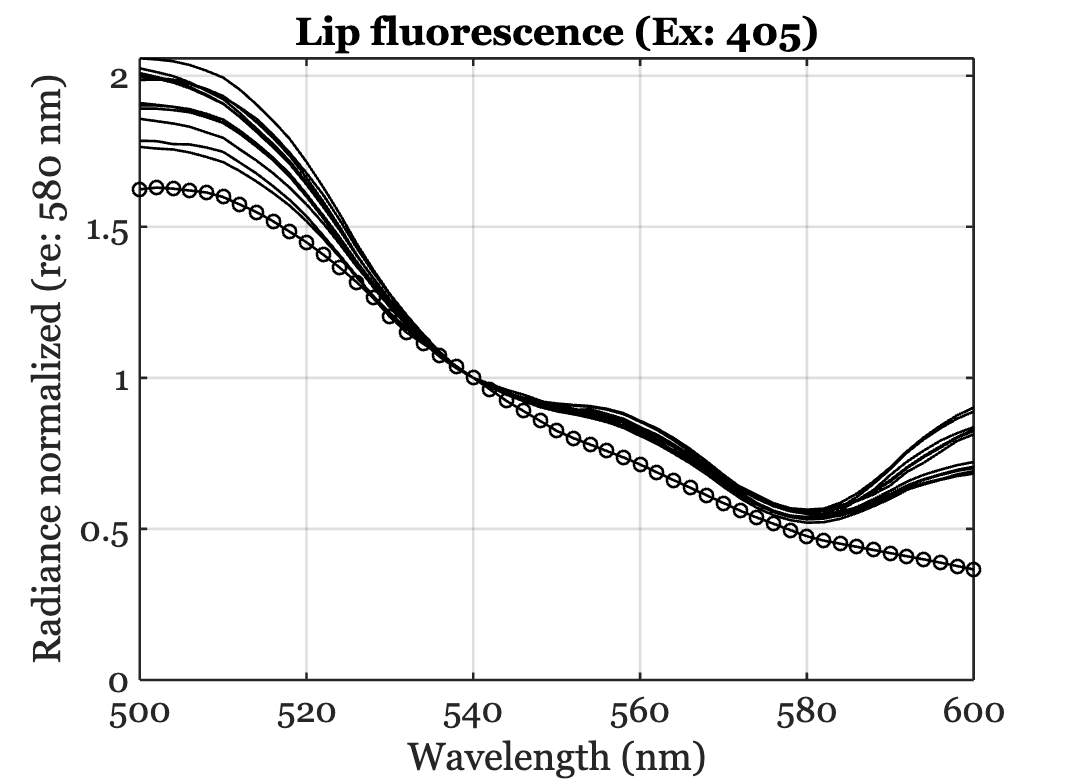

lip    = ieReadSpectra('MucosaMallia2008.mat',waves);
lip = lip/lip(waves == 540);

eWave = 405;
files405 = ieTableGet(T,...
    'substrate','lip', ...
    'ewave',eWave);

data405 = oeReadFiles(files405,'waves',waves,'normalized wave',540);

ieFigure;
plot(waves,data405,'k-'); hold on;
plot(waves,lip,'ko-');
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 580 nm)');
grid on; set(gca,'xlim',[500 600]);
title('Lip fluorescence (Ex: 405)');

## Fit Mallia cheek from our lip data

veldCheek = data405 * wgts

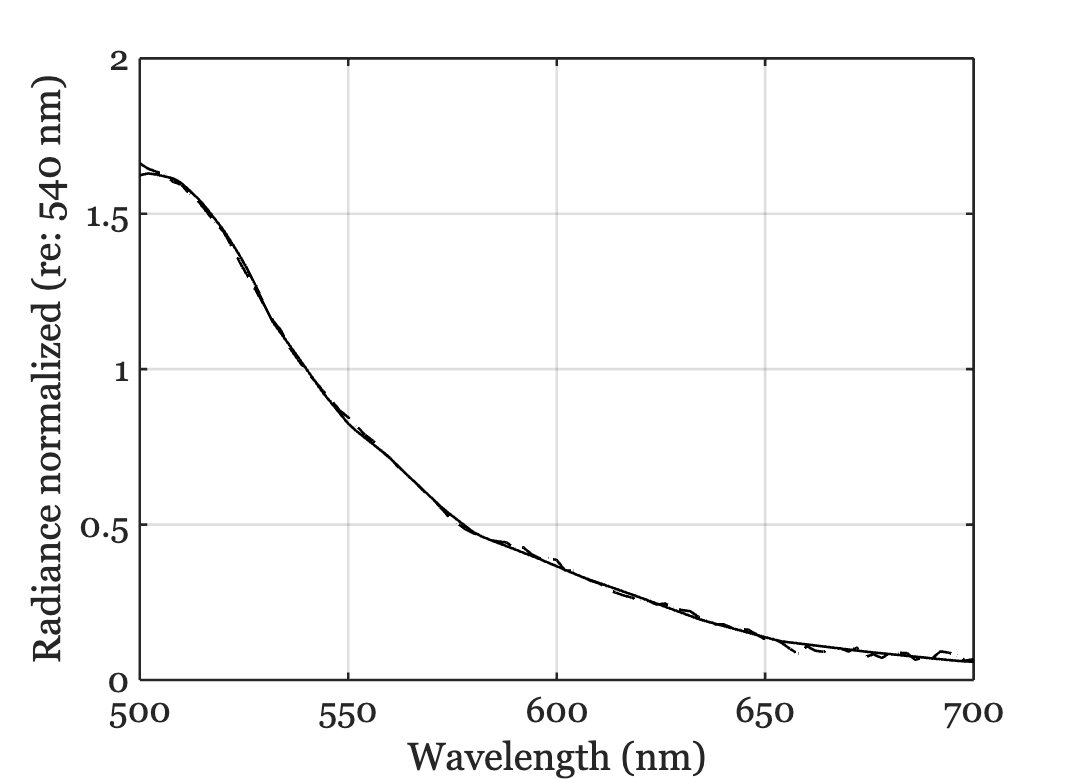

wgts = pinv(data405)*lip;
lipP = data405*wgts;

ieFigure;
plot(waves,lip,'k-',waves,lipP,'k--');
grid on;
xlabel('Wavelength (nm)');
ylabel('Radiance normalized (re: 540 nm)');

fprintf('Percent error: %.3f\n',sqrt(mean(((lip - lipP) ./ lipP).^2)));

Percent error: 0.083


fprintf('Absolute error: %.3f\n',sqrt(mean(((lip - lipP)).^2)));

Absolute error: 0.011


## Tongue, all subjects at 405 nm

Read in the files at all excitation levels

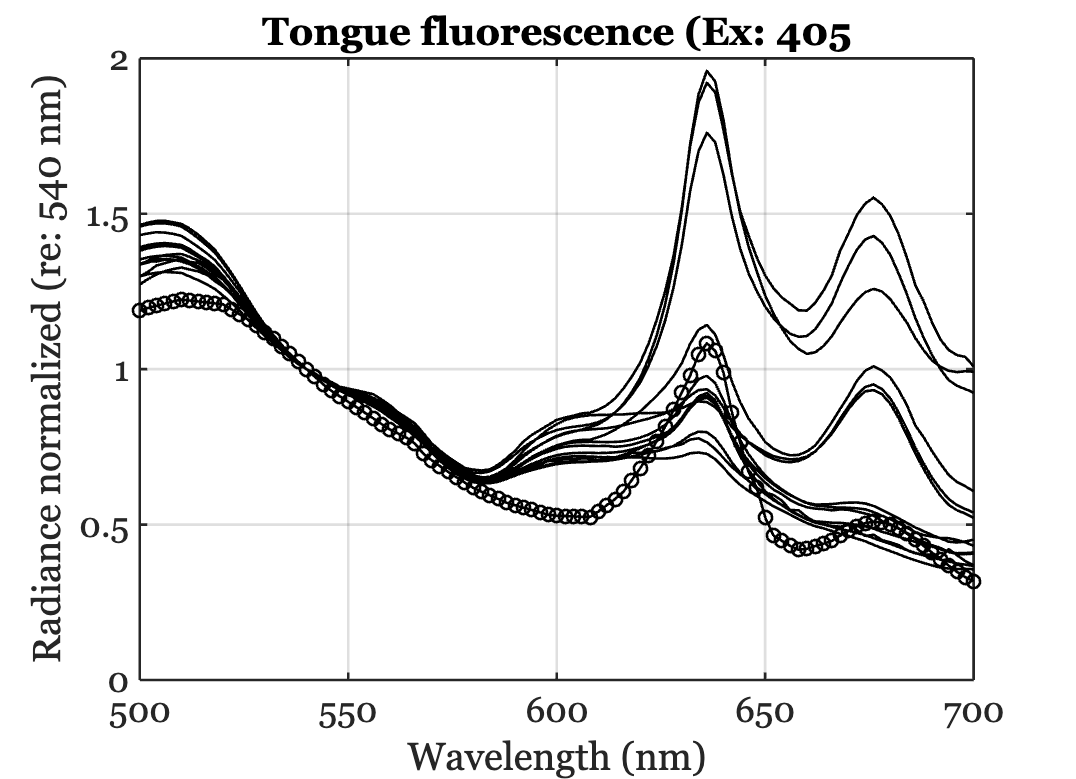

tongue = ieReadSpectra('DorsalTongueMallia2008.mat',waves);
tongue = tongue/tongue(waves == 540);


eWave = 405;
files405 = ieTableGet(T,...
    'substrate','tongue', ...
    'ewave',eWave);

data405 = oeReadFiles(files405,'waves',waves,'normalized wave',540);

ieFigure;
plot(waves,data405,'k-'); hold on;
plot(waves,tongue,'ko-');
xlabel('Wavelength (nm)'); ylabel('Radiance normalized (re: 540 nm)');
set(gca,'xlim',[500 700]); grid on;
title('Tongue fluorescence (Ex: 405');

## Fit Betz tongue from our tongues data

veldTongue = data405 * wgts

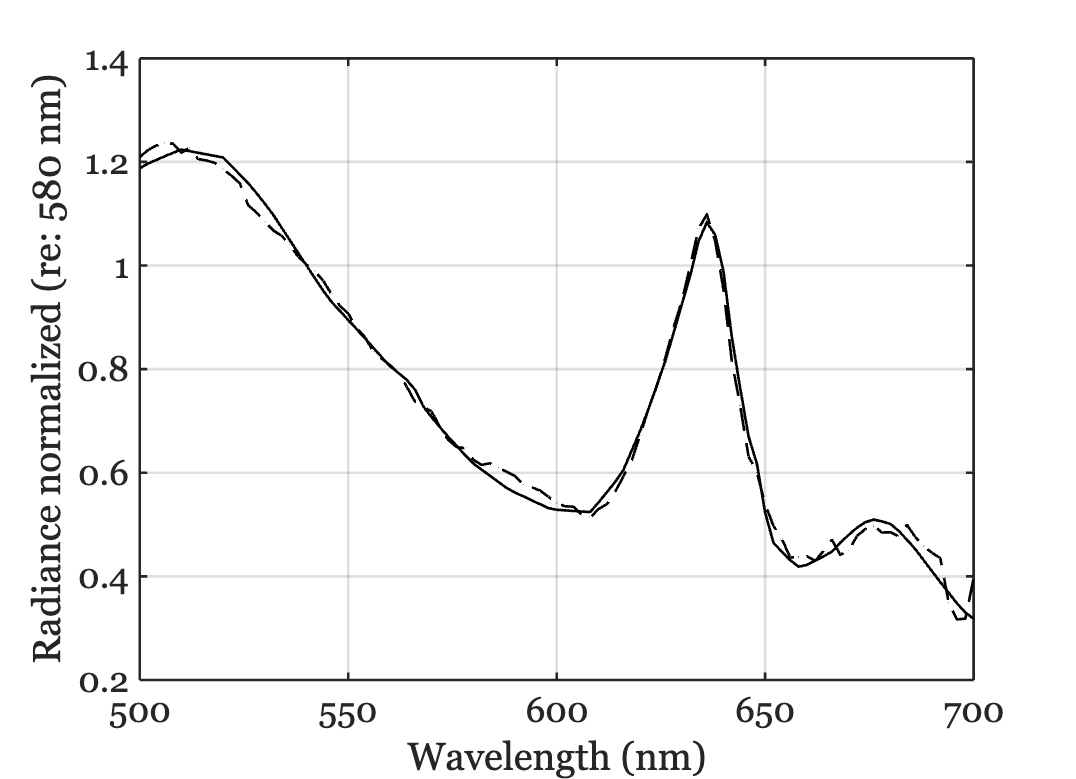

wgts = pinv(data405)*tongue;
tongueP = data405*wgts;

ieFigure;
plot(waves,tongue,'k-',waves,tongueP,'k--');
grid on;
xlabel('Wavelength (nm)'); 
ylabel('Radiance normalized (re: 580 nm)');

fprintf('Percent error: %.3f\n',sqrt(mean(((tongue - tongueP) ./ tongueP).^2)));

Percent error: 0.039


fprintf('Absolute error: %.3f\n',sqrt(mean(((tongue - tongueP)).^2)));

Absolute error: 0.022
